clear;
clc;
addpath(genpath('utils'));

load('data\filtering_data_from_ea.mat');
load('data\parameters_Stribeck_20230905_15_27.mat');
Symbol_Definition;
transform_physical_parameters_to_inertial_parameters;
g = 9.80665;

[n_sample, ~] = size(q_filt);
if exist('data\torque_Stribeck_ww_data_from_ea.mat', 'file')
    load('data\torque_Stribeck_ww_data_from_ea.mat', 'torque');
else
    load('data\torque_Stribeck.mat', 'torque');
    eval(subs(torque, {'ZZR1'}, {ZZR1}));

    eval(subs(torque, {'XXR2'}, {XXR2}));
    eval(subs(torque, {'XY2'}, {XY2}));
    eval(subs(torque, {'XZ2'}, {XZ2}));
    eval(subs(torque, {'YZ2'}, {YZ2}));
    eval(subs(torque, {'ZZR2'}, {ZZR2}));
    eval(subs(torque, {'MYR2'}, {MYR2}));

    eval(subs(torque, {'XXR3'}, {XXR3}));
    eval(subs(torque, {'XY3'}, {XY3}));
    eval(subs(torque, {'XZ3'}, {XZ3}));
    eval(subs(torque, {'YZ3'}, {YZ3}));
    eval(subs(torque, {'ZZR3'}, {ZZR3}));
    eval(subs(torque, {'MYR3'}, {MYR3}));

    eval(subs(torque, {'XXR4'}, {XXR4}));
    eval(subs(torque, {'XY4'}, {XY4}));
    eval(subs(torque, {'XZ4'}, {XZ4}));
    eval(subs(torque, {'YZ4'}, {YZ4}));
    eval(subs(torque, {'ZZR4'}, {ZZR4}));

    eval(subs(torque, {'XXR5'}, {XXR5}));
    eval(subs(torque, {'XY5'}, {XY5}));
    eval(subs(torque, {'XZ5'}, {XZ5}));
    eval(subs(torque, {'YZ5'}, {YZ5}));
    eval(subs(torque, {'ZZR5'}, {ZZR5}));
    eval(subs(torque, {'MYR5'}, {MYR5}));

    eval(subs(torque, {'XXR6'}, {XXR6}));
    eval(subs(torque, {'XY6'}, {XY6}));
    eval(subs(torque, {'XZ6'}, {XZ6}));
    eval(subs(torque, {'YZ6'}, {YZ6}));
    eval(subs(torque, {'ZZR6'}, {ZZR6}));
    eval(subs(torque, {'MYR6'}, {MYR6}));

    eval(subs(torque, {'XXR7'}, {XXR7}));
    eval(subs(torque, {'XY7'}, {XY7}));
    eval(subs(torque, {'XZ7'}, {XZ7}));
    eval(subs(torque, {'YZ7'}, {YZ7}));
    eval(subs(torque, {'ZZR7'}, {ZZR7}));
    eval(subs(torque, {'MYR7'}, {MYR7}));

    for k = 1 : n_sample

        q = q_filt(k, :);
        qd = qd_filt(k, :);
        qdd = qdd_filt(k, :);

        th1 = q(1); QP1 = qd(1); QDP1 = qdd(1);
        th2 = q(2); QP2 = qd(2); QDP2 = qdd(2);
        th3 = q(3); QP3 = qd(3); QDP3 = qdd(3);
        th4 = q(4); QP4 = qd(4); QDP4 = qdd(4);
        th5 = q(5); QP5 = qd(5); QDP5 = qdd(5);
        th6 = q(6); QP6 = qd(6); QDP6 = qdd(6);
        th7 = q(7); QP7 = qd(7); QDP7 = qdd(7);

        torque_ww(k, :) = eval(subs(torque, ...
            {'g', 'th1', 'QP1', 'QDP1', ...
            'th2', 'QP2', 'QDP2', ...
            'th3', 'QP3', 'QDP3', ...
            'th4', 'QP4', 'QDP4', ...
            'th5', 'QP5', 'QDP5', ...
            'th6', 'QP6', 'QDP6', ...
            'th7', 'QP7', 'QDP7'}, ...
            { g ,  th1 ,  QP1 ,  QDP1 , ...
            th2 ,  QP2 ,  QDP2 , ...
            th3 ,  QP3 ,  QDP3 , ...
            th4 ,  QP4 ,  QDP4 , ...
            th5 ,  QP5 ,  QDP5 , ...
            th6 ,  QP6 ,  QDP6 , ...
            th7 ,  QP7 ,  QDP7 }));

        fprintf('完成第%d帧数据的计算\n', k);
    end
    save('data\torque_Stribeck_ww_data_from_ea.mat', "torque_ww");
end

完成第1帧数据的计算
完成第2帧数据的计算
完成第3帧数据的计算
完成第4帧数据的计算
完成第5帧数据的计算
完成第6帧数据的计算
完成第7帧数据的计算
完成第8帧数据的计算
完成第9帧数据的计算
完成第10帧数据的计算
完成第11帧数据的计算
完成第12帧数据的计算
完成第13帧数据的计算
完成第14帧数据的计算
完成第15帧数据的计算
完成第16帧数据的计算
完成第17帧数据的计算
完成第18帧数据的计算
完成第19帧数据的计算
完成第20帧数据的计算
完成第21帧数据的计算
完成第22帧数据的计算
完成第23帧数据的计算
完成第24帧数据的计算
完成第25帧数据的计算
完成第26帧数据的计算
完成第27帧数据的计算
完成第28帧数据的计算
完成第29帧数据的计算
完成第30帧数据的计算
完成第31帧数据的计算
完成第32帧数据的计算
完成第33帧数据的计算
完成第34帧数据的计算
完成第35帧数据的计算
完成第36帧数据的计算
完成第37帧数据的计算
完成第38帧数据的计算
完成第39帧数据的计算
完成第40帧数据的计算
完成第41帧数据的计算
完成第42帧数据的计算
完成第43帧数据的计算
完成第44帧数据的计算
完成第45帧数据的计算
完成第46帧数据的计算
完成第47帧数据的计算
完成第48帧数据的计算
完成第49帧数据的计算
完成第50帧数据的计算
完成第51帧数据的计算
完成第52帧数据的计算
完成第53帧数据的计算
完成第54帧数据的计算
完成第55帧数据的计算
完成第56帧数据的计算
完成第57帧数据的计算
完成第58帧数据的计算
完成第59帧数据的计算
完成第60帧数据的计算
完成第61帧数据的计算
完成第62帧数据的计算
完成第63帧数据的计算
完成第64帧数据的计算
完成第65帧数据的计算
完成第66帧数据的计算
完成第67帧数据的计算
完成第68帧数据的计算
完成第69帧数据的计算
完成第70帧数据的计算
完成第71帧数据的计算
完成第72帧数据的计算
完成第73帧数据的计算
完成第74帧数据的计算
完成第75帧数据的计算
完成第76帧数据的计算
完成第77帧数据的计算
完成第78帧数据的计算
完成第79帧数据的计算
完成第80帧数据的计算
完成第81帧数据的计算
完成第82帧数据的计算
完成第83帧数据的计算
完成第84帧数据的计算
完

m1 = opt_x(1); m2 = opt_x(2); m3 = opt_x(3); m4 = opt_x(4); m5 = opt_x(5); m6 = opt_x(6); m7 = opt_x(7);MX1 = opt_x(8); MX2 = opt_x(9); MX3 = opt_x(10); MX4 = opt_x(11); MX5 = opt_x(12); MX6 = opt_x(13); MX7 = opt_x(14);
MY1 = opt_x(15); MY2 = opt_x(16); MY3 = opt_x(17); MY4 = opt_x(18); MY5 = opt_x(19); MY6 = opt_x(20); MY7 = opt_x(21);  
MZ1 = opt_x(22); MZ2 = opt_x(23); MZ3 = opt_x(24); MZ4 = opt_x(25); MZ5 = opt_x(26); MZ6 = opt_x(27); MZ7 = opt_x(28);
I1xx = opt_x(29); I1xy = opt_x(30); I1xz = opt_x(31); I1yy = opt_x(32); I1yz = opt_x(33); I1zz = opt_x(34); lc1x = opt_x(35); lc1y = opt_x(36); lc1z = opt_x(37);
I2xx = opt_x(38); I2xy = opt_x(39); I2xz = opt_x(40); I2yy = opt_x(41); I2yz = opt_x(42); I2zz = opt_x(43); lc2x = opt_x(44); lc2y = opt_x(45); lc2z = opt_x(46);
I3xx = opt_x(47); I3xy = opt_x(48); I3xz = opt_x(49); I3yy = opt_x(50); I3yz = opt_x(51); I3zz = opt_x(52); lc3x = opt_x(53); lc3y = opt_x(54); lc3z = opt_x(55);
I4xx = opt_x(56); I4xy = opt_x(57); I4xz = opt_x(58); I4yy = opt_x(59); I4yz = opt_x(60); I4zz = opt_x(61); lc4x = opt_x(62); lc4y = opt_x(63); lc4z = opt_x(64);
I5xx = opt_x(65); I5xy = opt_x(66); I5xz = opt_x(67); I5yy = opt_x(68); I5yz = opt_x(69); I5zz = opt_x(70); lc5x = opt_x(71); lc5y = opt_x(72); lc5z = opt_x(73);
I6xx = opt_x(74); I6xy = opt_x(75); I6xz = opt_x(76); I6yy = opt_x(77); I6yz = opt_x(78); I6zz = opt_x(79); lc6x = opt_x(80); lc6y = opt_x(81); lc6z = opt_x(82);
I7xx = opt_x(83); I7xy = opt_x(84); I7xz = opt_x(85); I7yy = opt_x(86); I7yz = opt_x(87); I7zz = opt_x(88); lc7x = opt_x(89); lc7y = opt_x(90); lc7z = opt_x(91);
fc1 = opt_x(92); fs1 = opt_x(93); vs1 = opt_x(94); fv1 = opt_x(95);
fc2 = opt_x(96); fs2 = opt_x(97); vs2 = opt_x(98); fv2 = opt_x(99);
fc3 = opt_x(100); fs3 = opt_x(101); vs3 = opt_x(102); fv3 = opt_x(103);
fc4 = opt_x(104); fs4 = opt_x(105); vs4 = opt_x(106); fv4 = opt_x(107);
fc5 = opt_x(108); fs5 = opt_x(109); vs5 = opt_x(110); fv5 = opt_x(111);
fc6 = opt_x(112); fs6 = opt_x(113); vs6 = opt_x(114); fv6 = opt_x(115);
fc7 = opt_x(116); fs7 = opt_x(117); vs7 = opt_x(118); fv7 = opt_x(119);

T_idy = eval(subs(torque_ww, {'m1', 'm2', 'm3', 'm4', 'm5', 'm6', 'm7', ...
    'MX1', 'MX2', 'MX3', 'MX4', 'MX5', 'MX6', 'MX7', ...
    'MY1', 'MY2', 'MY3', 'MY4', 'MY5', 'MY6', 'MY7', ...
    'MZ1', 'MZ2', 'MZ3', 'MZ4', 'MZ5', 'MZ6', 'MZ7', ...
    'I1xx', 'I1xy', 'I1xz', 'I1yy', 'I1yz', 'I1zz', 'lc1x', 'lc1y', 'lc1z', ...
    'I2xx', 'I2xy', 'I2xz', 'I2yy', 'I2yz', 'I2zz', 'lc2x', 'lc2y', 'lc2z', ...
    'I3xx', 'I3xy', 'I3xz', 'I3yy', 'I3yz', 'I3zz', 'lc3x', 'lc3y', 'lc3z', ...
    'I4xx', 'I4xy', 'I4xz', 'I4yy', 'I4yz', 'I4zz', 'lc4x', 'lc4y', 'lc4z', ...
    'I5xx', 'I5xy', 'I5xz', 'I5yy', 'I5yz', 'I5zz', 'lc5x', 'lc5y', 'lc5z', ...
    'I6xx', 'I6xy', 'I6xz', 'I6yy', 'I6yz', 'I6zz', 'lc6x', 'lc6y', 'lc6z', ...
    'I7xx', 'I7xy', 'I7xz', 'I7yy', 'I7yz', 'I7zz', 'lc7x', 'lc7y', 'lc7z', ...
    'fc1' 'fs1' 'vs1' 'fv1', ...
    'fc2' 'fs2' 'vs2' 'fv2', ...
    'fc3' 'fs3' 'vs3' 'fv3', ...
    'fc4' 'fs4' 'vs4' 'fv4', ...
    'fc5' 'fs5' 'vs5' 'fv5', ...
    'fc6' 'fs6' 'vs6' 'fv6', ...
    'fc7' 'fs7' 'vs7' 'fv7'}, ...
    {m1, m2, m3, m4, m5, m6, m7, ...
    MX1, MX2, MX3, MX4, MX5, MX6, MX7, ...
    MY1, MY2, MY3, MY4, MY5, MY6, MY7, ...
    MZ1, MZ2, MZ3, MZ4, MZ5, MZ6, MZ7, ...
    I1xx, I1xy, I1xz, I1yy, I1yz, I1zz, lc1x, lc1y, lc1z, ...
    I2xx, I2xy, I2xz, I2yy, I2yz, I2zz, lc2x, lc2y, lc2z, ...
    I3xx, I3xy, I3xz, I3yy, I3yz, I3zz, lc3x, lc3y, lc3z, ...
    I4xx, I4xy, I4xz, I4yy, I4yz, I4zz, lc4x, lc4y, lc4z, ...
    I5xx, I5xy, I5xz, I5yy, I5yz, I5zz, lc5x, lc5y, lc5z, ...
    I6xx, I6xy, I6xz, I6yy, I6yz, I6zz, lc6x, lc6y, lc6z, ...
    I7xx, I7xy, I7xz, I7yy, I7yz, I7zz, lc7x, lc7y, lc7z, ...
    fc1, fs1, vs1, fv1, ...
    fc2, fs2, vs2, fv2, ...
    fc3, fs3, vs3, fv3, ...
    fc4, fs4, vs4, fv4, ...
    fc5, fs5, vs5, fv5, ...
    fc6, fs6, vs6, fv6, ...
    fc7, fs7, vs7, fv7}));

T = t_filt;

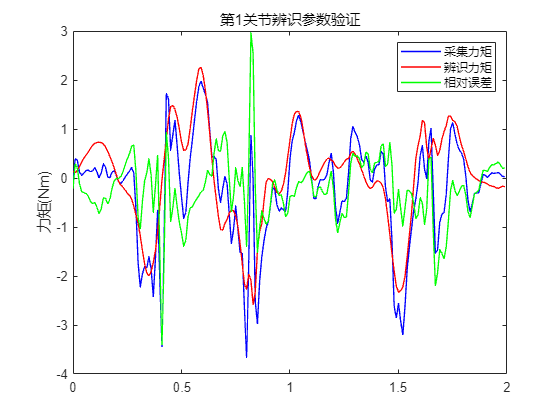

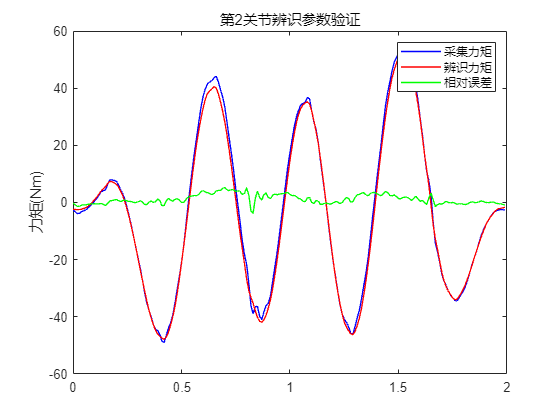

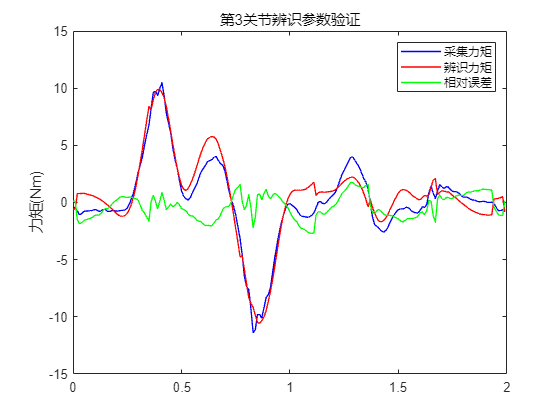

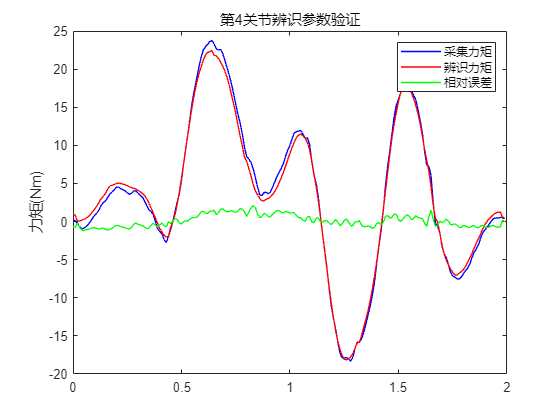

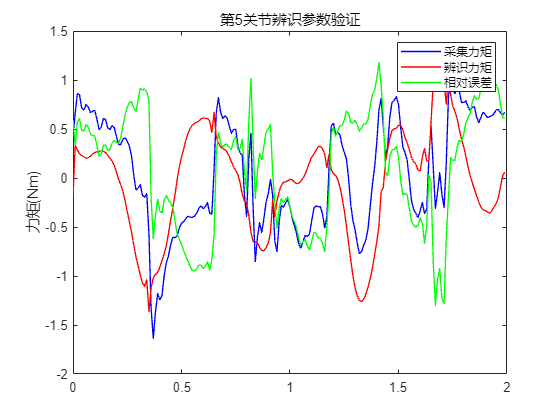

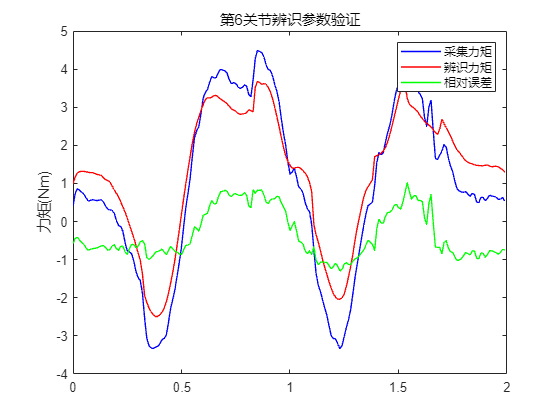

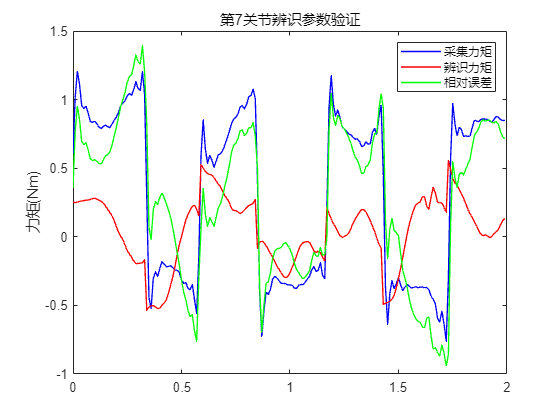

traj_Ts = 0.01;
[n_sample, ~] = size(q_filt);
t = linspace(0, n_sample - 1, n_sample) * traj_Ts;

for ii = 1:7
    figure(ii);
    plot(t, T(:, ii), 'b', 'LineWidth', 1.0); hold on;
    plot(t, T_idy(:, ii), 'r', 'LineWidth', 1.0);
    plot(t, T(:, ii) - T_idy(:, ii), 'g', 'LineWidth', 1.0); hold off;
    ylabel('力矩(Nm)');
    legend('采集力矩', '辨识力矩', '相对误差')
    title(['第', num2str(ii), '关节辨识参数验证'])
    % print(ii, '-dpng', '-r600', ['.\figs\idy\idy', num2str(ii), '.png']);
end

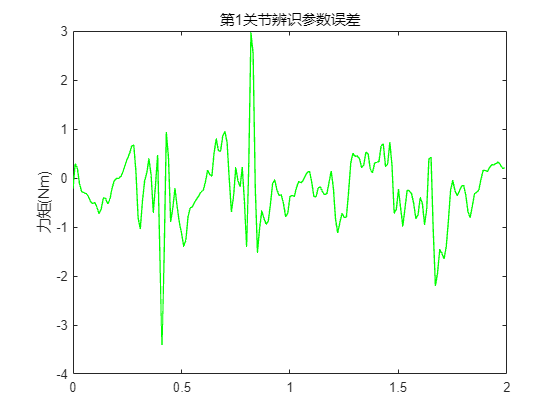

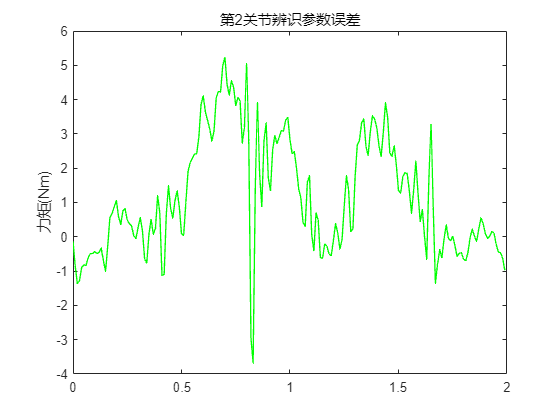

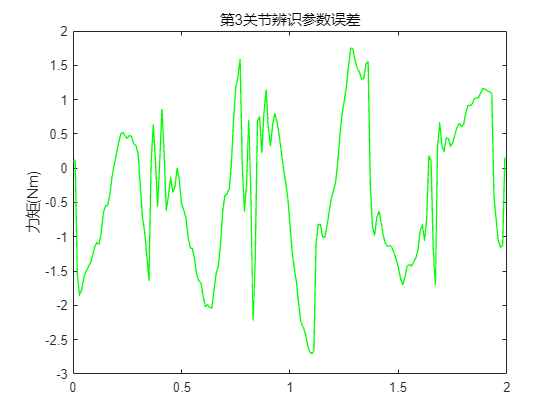

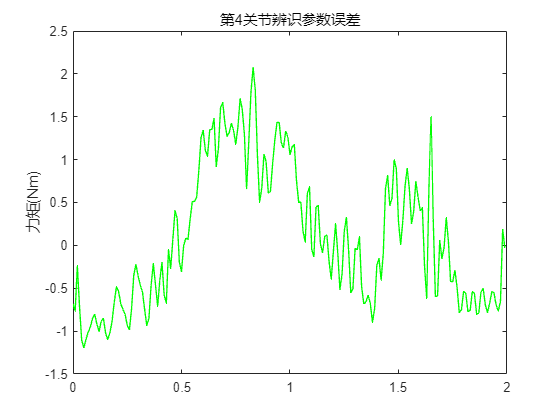

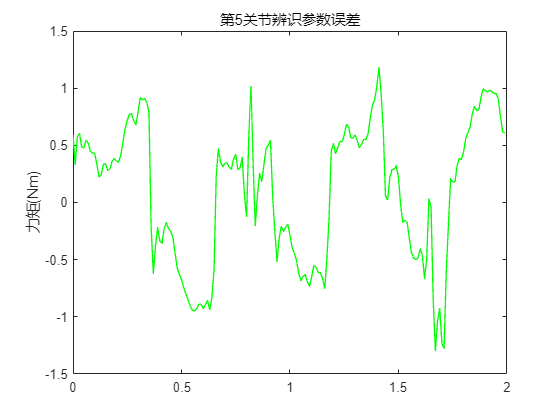

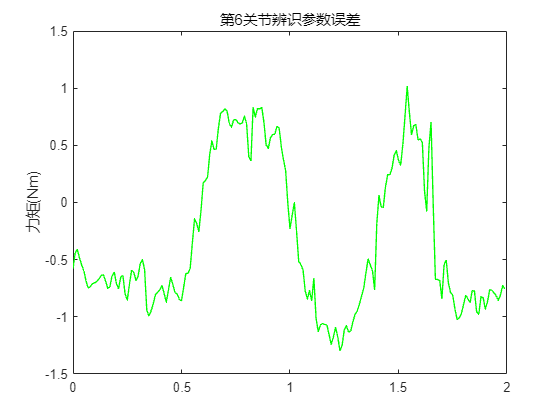

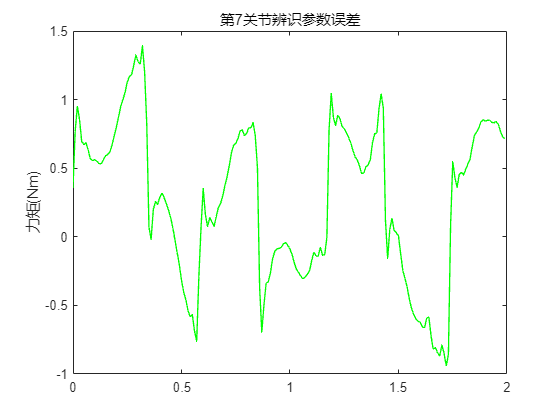

for jj = 1:7
    figure(jj + 7);
    plot(t, T(:, jj) - T_idy(:, jj), 'g', 'LineWidth', 1.0);
    title(['第', num2str(jj), '关节辨识参数误差']);
    ylabel('力矩(Nm)')
    % print(7 + jj, '-dpng', '-r600', ['.\figs\diff\diff', num2str(jj), '.png']);
end

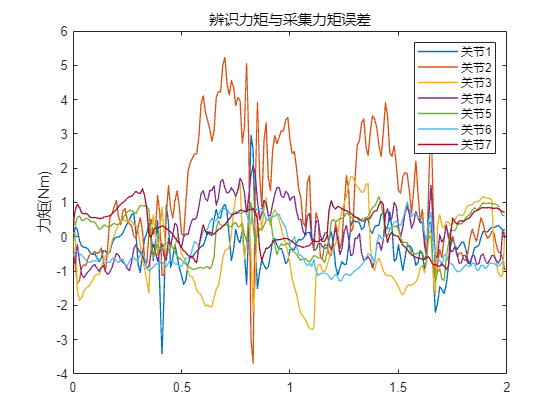

error = zeros(7, 1);
figure(15)
for kk = 1:7
    plot(t, T(:, kk) - T_idy(:, kk), 'LineWidth', 1.0); hold on;
    error(kk) = sum((T(:, kk) - T_idy(:, kk)).^2);
end

ylabel('力矩(Nm)');
legend('关节1', '关节2', '关节3', '关节4', '关节5', '关节6', '关节7')
title('辨识力矩与采集力矩误差')